**Data**

x = [1 2 3 4 5]';

y = [2.2 2.8 3.6 4.5 5.5]';


**Plot data**

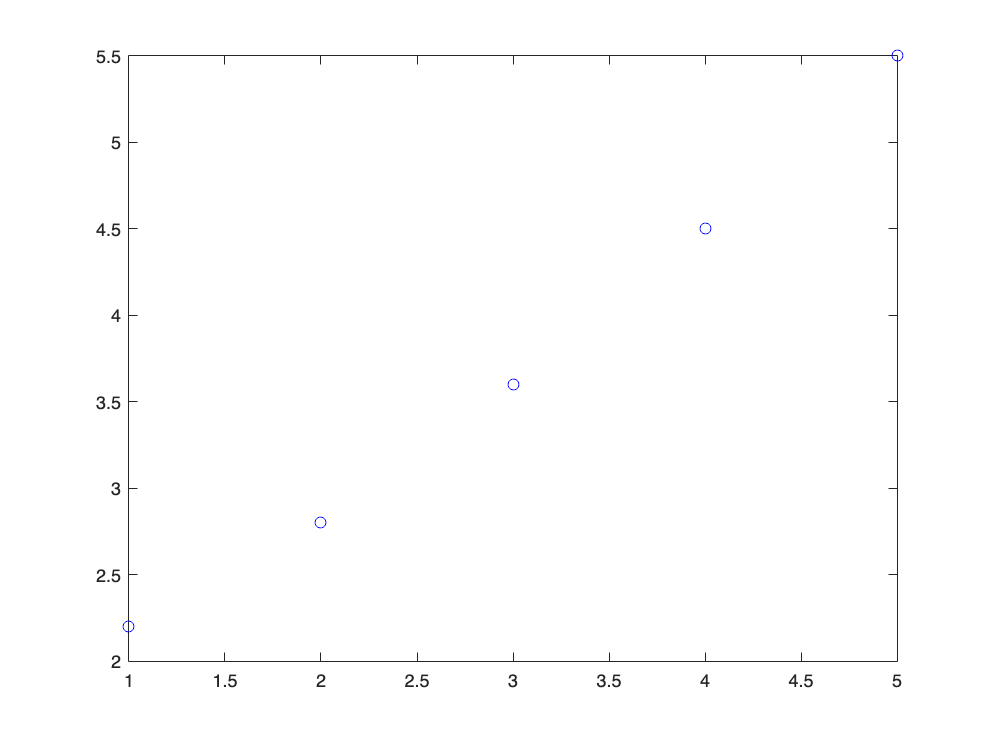

% No need to plot a graph
plot(x, y, 'bo')

**Create Z matrix**

Z = [ones(size(x))    x     1./x]

Z =     1.0000    1.0000    1.0000
    1.0000    2.0000    0.5000
    1.0000    3.0000    0.3333
    1.0000    4.0000    0.2500
    1.0000    5.0000    0.2000


**Solve for unknown parameters  a  **

a = (Z'*Z) \ (Z'*y)

a =     0.3745
    0.9864
    0.8456


**Plot data and the best fitted curve**

% No need to plot a graph
xp = linspace(min(x), max(x), 100)

xp =     1.0000    1.0404    1.0808    1.1212    1.1616    1.2020    1.2424    1.2828    1.3232    1.3636    1.4040    1.4444    1.4848    1.5253    1.5657    1.6061    1.6465    1.6869    1.7273    1.7677    1.8081    1.8485    1.8889    1.9293    1.9697    2.0101    2.0505    2.0909    2.1313    2.1717    2.2121    2.2525    2.2929    2.3333    2.3737    2.4141    2.4545    2.4949    2.5354    2.5758    2.6162    2.6566    2.6970    2.7374    2.7778    2.8182    2.8586    2.8990    2.9394    2.9798


yp = a(1) + a(2) .* xp

yp =     1.3609    1.4008    1.4407    1.4805    1.5204    1.5602    1.6001    1.6399    1.6798    1.7196    1.7595    1.7994    1.8392    1.8791    1.9189    1.9588    1.9986    2.0385    2.0784    2.1182    2.1581    2.1979    2.2378    2.2776    2.3175    2.3573    2.3972    2.4371    2.4769    2.5168    2.5566    2.5965    2.6363    2.6762    2.7161    2.7559    2.7958    2.8356    2.8755    2.9153    2.9552    2.9950    3.0349    3.0748    3.1146    3.1545    3.1943    3.2342    3.2740    3.3139


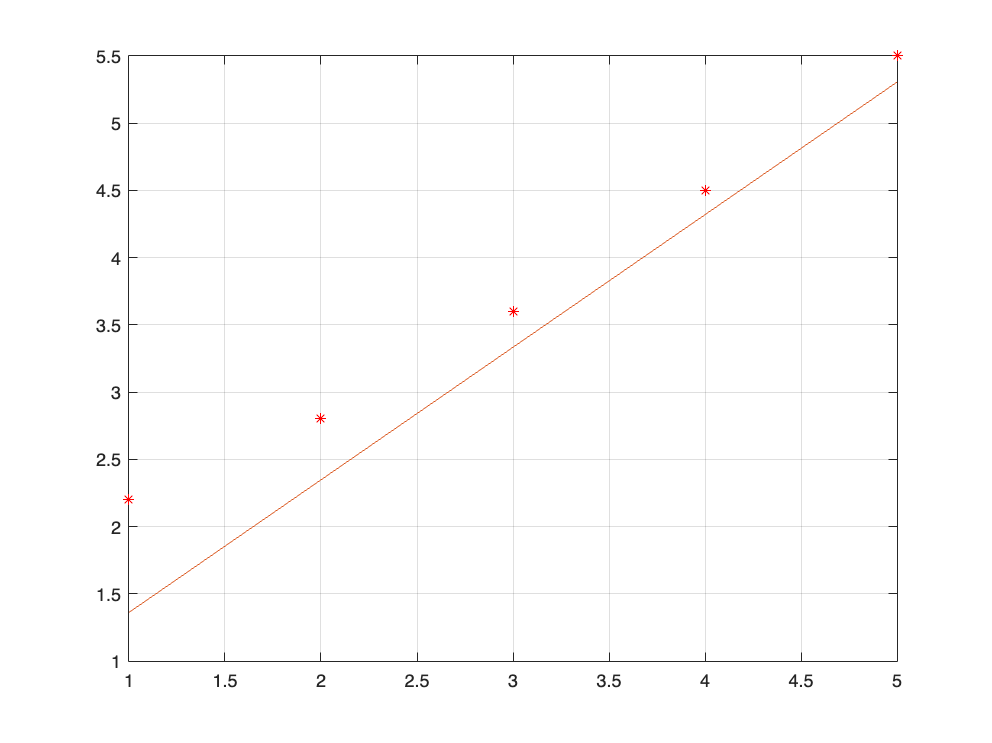

plot(x, y, 'r*', xp, yp)
grid on

**Compute  Sr  (the sum of the squares of the residuals between the best-fit curve and the data)**

Sr = sum((y - Z*a) .^ 2)

Sr = 0.0028

**Compute  St   (the sum of the squares of the residuals between the data points and the mean)**

St = sum((y - mean(y)) .^ 2)

St = 6.9480

**Compute  r2  (the coefficient of determination)**

r2 = 1 - (Sr/St)

r2 = 0.9996

**Compute  syx  (the standard error of the estimate)  **

syx = sqrt(Sr / (length(y) - length(a)))

syx = 0.0372

**Predict the value of y for the given x**

xtest = 2.5

xtest = 2.5000

ytest = a(1) + (a(2) * xtest) + (a(3) * (1 / xtest))

ytest = 3.1789